# Processing a baby cry

## Choose a baby cry to sound

file = "baby_cry_1.wav";
[data, fs] = audioread(file);
sound(data, fs);

## Time domain processing

#### Plot baby cry in time domain

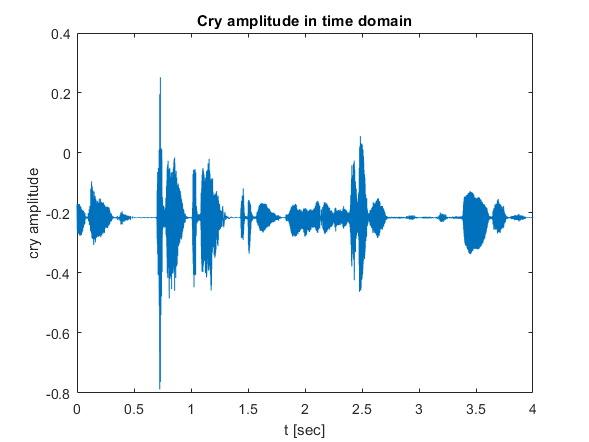

file = "baby_cry_2.wav";
[data, fs] = audioread(file);
duration = round(length(data) / fs);
t = linspace(0, duration, length(data));
plot(t, data);
title('Cry amplitude in time domain');
xlabel('t [sec]');
ylabel('cry amplitude');

## Frequency domain processing

#### Plot baby cry in frequency domain

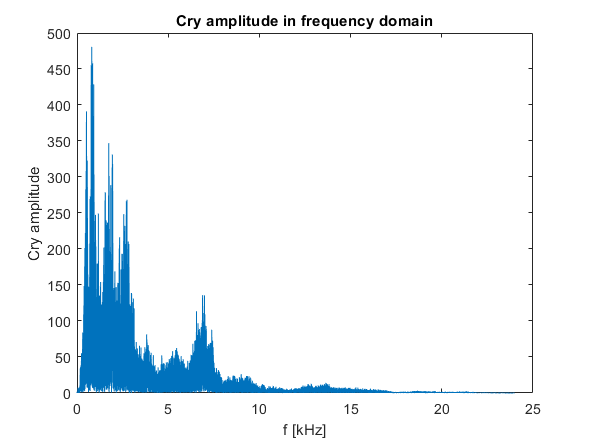

file = "baby_cry_3.wav";
[data, fs] = audioread(file);
f = linspace(0, fs/2, round(length(data)/2)-1);
dataFft = fft(data);
plot(f*1e-3, abs(dataFft(2:round(length(dataFft)/2))));
title('Cry amplitude in frequency domain');
xlabel('f [kHz]');
ylabel('Cry amplitude');

#### Focus on prominent frequencies

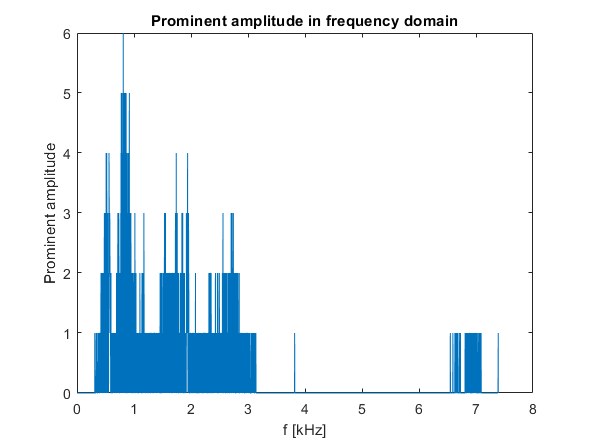

ampThresh = 80;
amp = abs(dataFft(2:round(length(dataFft)/2)));
amp = floor(amp/ampThresh);
idx = find(amp);
f = f(1:idx(end)+10);
plot(f*1e-3, amp(1:idx(end)+10));
title('Prominent amplitude in frequency domain');
xlabel('f [kHz]');
ylabel('Prominent amplitude');